## ** Número I: 10**

# **Análise e Modelagem de Sistemas Dinâmicos - 2023/2**

## Nome: Thiago Felippe Neitzke Lahass

## Data limite para entrega: 18/10/2023

### A entrega deverá ser feita pelo Google ClassRoom

# Trabalho 2 - Sistemas no Espaço de Estados e Linearização

I = 10;          % Seu número I
init_t2(I);     % Define as variaveis dos modelos
datetime('now')

ans = datetime
   26-Oct-2023 22:38:25


## Linearização do Modelo de Válvula Carretel (Spool Valve)

O vídeo abaixo mostra o funcionamento de uma válvula carretel de 4 vias.

% ShowVideo; % Este código pode ser comentado (o vídeo é apenas para ilustrar o funcionamento da válvula)

A Figura abaixo mostra o esquemático de uma válvula carretel de três vias empregada para controlar a vazão em um sistema hidráulico, cujo funcionamento é semelhante à válvula carretel mostrada no vídeo acima.

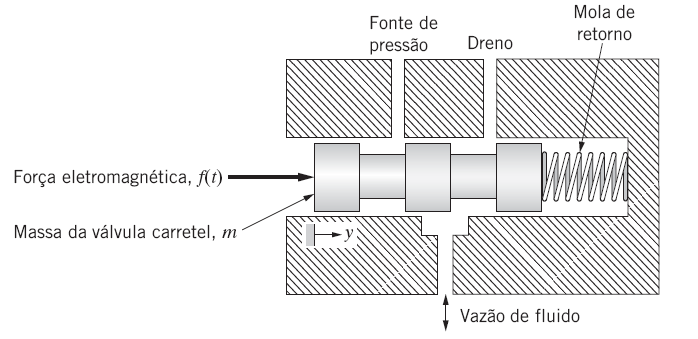

O modelo matemático da válvula carretel consiste em uma única massa ($m\;\left\lbrack \textrm{kg}\right\rbrack$), uma força de atrito linear ($b\;\left\lbrack N\ldotp s/m\right\rbrack$) e uma força de mola linear ($k\;\left\lbrack N/m\right\rbrack$). A variável $y\left(t\right)$ é de deslocamento da válvula carretel (em $\left\lbrack m\right\rbrack$) e $f\left(t\right)$ é a força de um atuador eletromagnético que empurra a válvula (em $\left\lbrack N\right\rbrack$). Assume-se que não existe desequilíbrio na pressão do fluido hidráulico sobre a massa da válvula, e que as forças de fluxo são desprezadas; assim, a força do atuador $f\left(t\right)$ é a única aplicada sobre a massa da válvula. O sistema inicialmente está em repouso (${\dot{y} }_0 =y_0 =0$) no instante $t=0\;\left\lbrack s\right\rbrack$.

**Funções úteis do Matlab:** tf, step, stepDataOptions, lsim, figure, plot, grid, yyaxis, title, xlabel, ylabel, sprintf, linspace.

### 1.1 Usanto o simulink, elabore um diagrama de blocos do modelo dinâmico da válvula (Equação Diferencial) e simule para uma força que varia de $f_{\textrm{inicial}} \;\left\lbrack N\right\rbrack$ a $f_{\textrm{final}} \;\left\lbrack N\right\rbrack$ no instante $t_{\textrm{inicial}} \;\left\lbrack s\right\rbrack$.

**OBS: **

**1) A saída do modelo deve ser um conector do tipo "Out1" disponível na biblioteca "Sinks". **

**2) Escolha um tempo de simulação de aproximadamente 0,1[s] de operação em regime permanente.**

Temos pelo enunciado que a única força aplicada sobre a massa da válvula é $f\left(t\right)$, então, Pela Segunda Lei de Newton, temos que:

$m\ddot{y} \left(t\right)=f\left(t\right)-b\dot{y} \left(t\right)-k\;y\left(t\right)$                   (1).

 Dado que as condições inicias são nulas, aplicando Laplace obtemos:

${m\ldotp s}^2 \;Y\left(s\right)=F\left(s\right)-b\ldotp s\;Y\left(s\right)-k\;Y\left(s\right)$       (2).

Logo, a função de transferência $G_1 \left(s\right)$ entre a a entrada $f\left(t\right)$ e a saída $y\left(t\right)$, é:

$G_1 \left(s\right)=\frac{Y\left(s\right)}{F\left(s\right)}=\frac{1}{{m\ldotp s}^2 +b\ldotp s+k}$                (3).

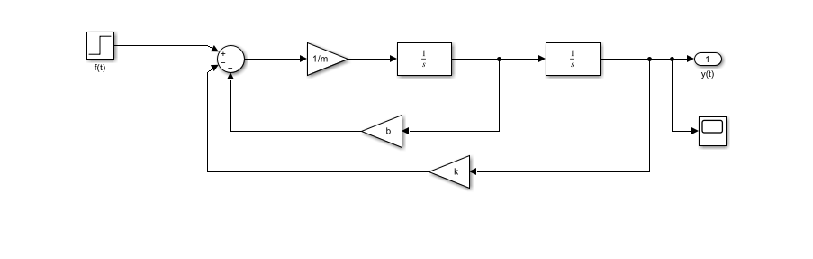

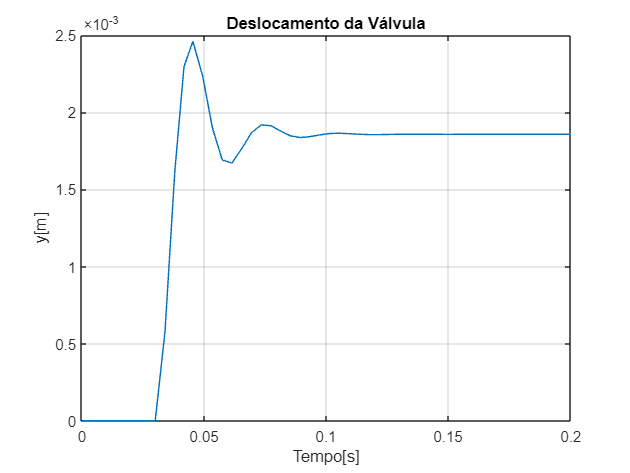

% modelo = 'Nome'; % Coloque o nome do arquivo feito no Simulink sem a extensão .slx
modelo1 = 'G1';

[y1,t1] = snapshotModel(modelo1);

### 1.2 Considere que, por desgaste, uma força de atrito seco $f_s \left(t\right)$ passe a compor o atrito da válvula juntamente com o atrito viscoso pré existente. A equação do atrito seco possui uma componente $f_a \left(t\right)$que atua em sentido contrário ao movimento, como mostrado abaixo. 

### 
$$f_s \left(t\right)=f_a \left(t\right)\frac{\dot{y} \left(t\right)}{\left|\dot{y} \left(t\right)\right|}\;\left\lbrack N\right\rbrack$$


### a) É possível simular (no simulink) o modelo com a não linearidade acima? Explique.

Não, pois a não linearidade vista é uma não linearidade dura do tipo on-off, causando problemas na simulação por causa da descontinuidade na velocidade ($\dot{y} \left(t\right)$) zero, e portanto não sendo possível realizar a simulação do sistema.

### b) Se a afirmativa anterior for verdadeira, simule, no simulink, para uma força que varia de $f_{\textrm{inicial}} \;\left\lbrack N\right\rbrack$ a $f_{\textrm{final}} \;\left\lbrack N\right\rbrack$ no instante $t_{\textrm{inicial}} \;\left\lbrack s\right\rbrack$. Senão, estabeleça uma forma de modelar a não linearidade e simule para as mesmas condições.

**OBS: **

**1) A saída do modelo deve ser um conector do tipo "Out1" disponível na biblioteca "Sinks". **

**2) Escolha um tempo de simulação de aproximadamente 0,1[s] de operação em regime permanente.**

Como o sistema com a linearidade dura vista não pode ser simulado, é necessário estabelecer uma forma de modelá-lo para que a função de atrito seco se torne contínua, para que assim o sistema possa ser simulado. Podemos aproximar a força de atrito seco para:

$f_s \left(t\right)=f_a \left(t\right)\left(\frac{\dot{y} \left(t\right)}{\sqrt{\dot{y} \left(t\right)+\mu^2 }}\right)\;\left\lbrack N\right\rbrack$, onde $\mu$ é um valor pequeno ($\mu \cong {10}^{-4} \;\left\lbrack m\;/\;s\right\rbrack$).

Portanto, a nova equação que rege o sistema passa a ser:

$m\ddot{y} \left(t\right)=f\left(t\right)-b\dot{y} \left(t\right)-\textrm{ky}\left(t\right)-f_s \left(t\right)$,

ou, substituindo:

$m\ddot{y} \left(t\right)=f\left(t\right)-b\dot{y} \left(t\right)-\textrm{ky}\left(t\right)-f_a \left(t\right)\left(\frac{\dot{y} \left(t\right)}{\sqrt{\dot{y} \left(t\right)+\mu^2 }}\right)$.

Finalmente, basta montar o diagrama de blocos correspondente para adicionar o atrito seco ao sistema:

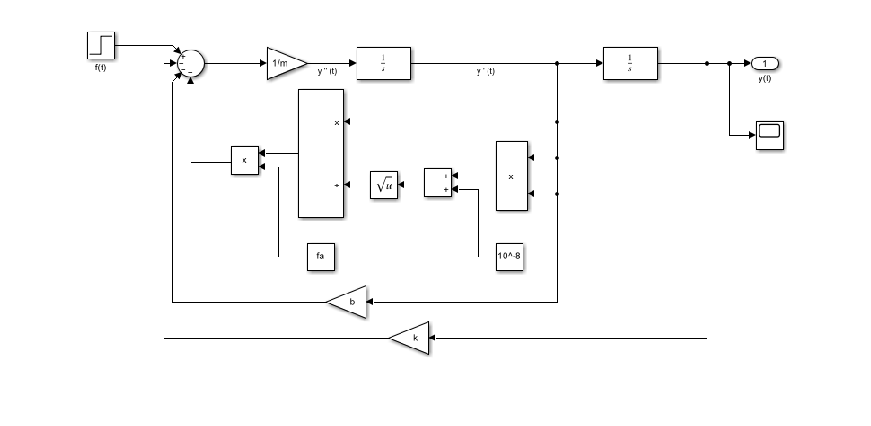

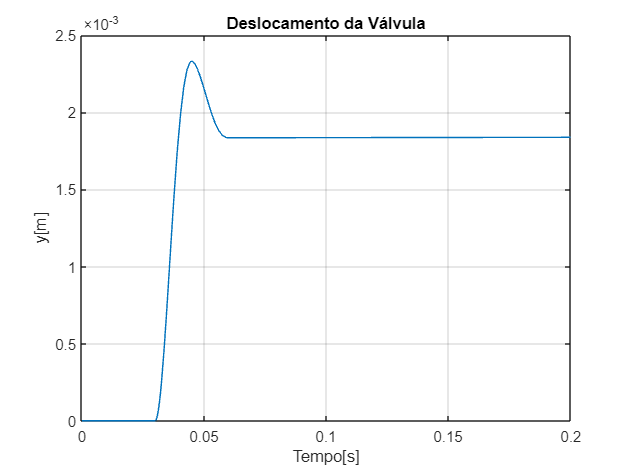

% modelo = 'Nome'; % Coloque o nome do arquivo feito no Simulink sem a extensão .slx
modelo2 = 'G2';
[y2,t2] = snapshotModel(modelo2);

### c) Compare a resposta da válvula sem o atrito seco com a resposta com o atrito seco linearizado.

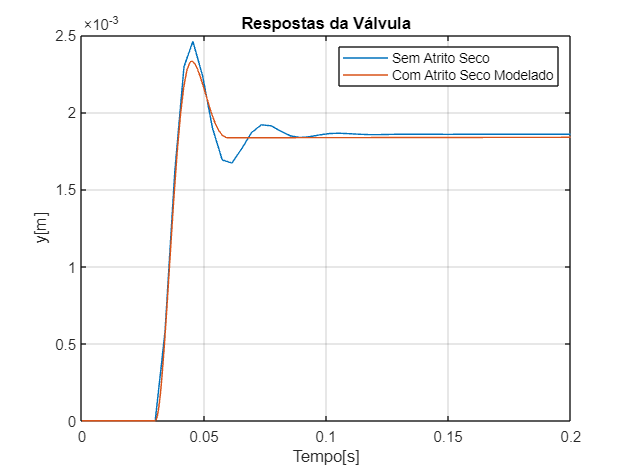

% Gráficos para comparação
figure;
plot(t1,y1)
hold on
plot(t2,y2)
grid on
legend('Sem Atrito Seco','Com Atrito Seco Modelado')
xlabel('Tempo[s]')
ylabel('y[m]')
title('Respostas da Válvula')
hold off

Vemos, portanto, que o atrito seco não é proporcional à velocidade da massa, mas sim uma componente de força constante cujo sinal depende da velocidade, logo se opõe ao movimento de forma diferente do atrito viscoso. É visto que a consideração do atrito seco faz com que o sistema oscile menos, permitindo que ele se estabilize mais rapidamente.

## Análise dos Estados de um Conjunto de Vagões Interligados

A Figura abaixo mostra um conjunto de três vagões interligados. A ligação entre eles pode ser modelada como um par mola-amortecedor. A motorização do comboio é feita no vagão de trás, gerando uma força $u_1(t)$, enquanto a frenagem é feita no vagão da frente, gerando uma força $u_2(t)$. A posição dos vagões é obtida a partir de um ponto de referência O, sendo que o vagão 1 inicia a uma distancia $L_1$ de O. As distâncias $L_2$ e $L_3|$ são tais que os conjuntos mola-amorteceor encontram-se em repouso.

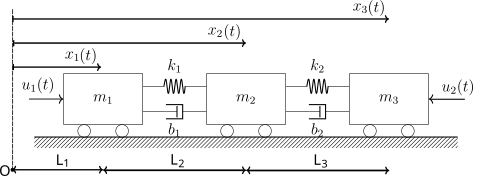

### 2.1 Considere as posições $x_1(t)$, $x_2(t)$, $x_3(t)$, e as velocidades $\dot{x}_1(t)$, $\dot{x}_2(t)$, $\dot{x}_3(t)$, como estados. O modelo em espaço de estados será linear? Justifique sua resposta.

Não, pois as condições iniciais ($L_1 ,{\;L}_2$ e $L_3$) deslocam o sistema da origem, tonando-o um sistema não linear, mas sim afim.

### 2.2 Represente o modelo do sistema no Espaço de Estados (linearize o sistema, caso seja necessário), sendo $u_1(t)$ e $u_2(t)$ as entradas e, as posições de cada vagão, as saídas.

Seja $\delta x_1 =x_1 \left(t\right)-L_1$, $\delta x_2 =x_2 \left(t\right)-L_1 -L_2$ e $\delta x_3 =x_3 \left(t\right)-L_1 -L_2 -L_3$, supondo ${\delta x}_1 >{\delta x}_2 >{\delta x}_3$, temos:

    Para o vagão de massa $m_1$:

        
$$m_1 \delta {\ddot{x} }_1 =u_1 -k_1 \left(\delta x_1 -{\delta x}_2 \right)-b_1 \left({\dot{\delta x} }_1 -{\dot{\delta x} }_2 \right)$$


         $m_1 {\ddot{x} }_1 =u_1 -k_1 \left(x_1 -x_2 +L_2 \right)-b_1 \left({\dot{x} }_1 -{\dot{x} }_2 \right)$                                                   (1).

    Para o vagão de massa $m_2$:

        
$$m_2 {\ddot{\delta x} }_2 =k_1 \left(\delta x_1 -{\delta x}_2 \right)+b_1 \left(\delta {\dot{x} }_1 -{\delta \dot{x} }_2 \right)-k_2 \left({\delta x}_2 -{\delta x}_3 \right)-b_2 \left(\delta {\dot{x} }_2 -{\delta \dot{x} }_3 \right)$$


        $m_2 {\ddot{x} }_2 =k_1 \left(x_1 -x_2 +L_2 \right)+b_1 \left({\dot{x} }_1 -{\dot{x} }_2 \right)-k_2 \left(x_2 -x_3 +L_3 \right)-b_2 \left({\dot{x} }_2 -{\dot{x} }_3 \right)$         (2).

    Finalmente, para o vagão de massa $m_3$:

        
$$m_3 \delta {\ddot{x} }_3 =-u_2 +k_2 \left(\delta x_2 -{\delta x}_3 \right)+b_2 \left({\delta \dot{x} }_2 -{\delta \dot{x} }_3 \right)$$


        $m_3 {\ddot{x} }_3 =-u_2 +k_2 \left(x_2 -x_3 +L_3 \right)+b_2 \left({\dot{x} }_2 -{\dot{x} }_3 \right)$                                                  (3).

Podemos definir os estados como:


$$\begin{array}{l}
q_1 =x_1 \\
q_2 ={\dot{x} }_1 \\
q_3 =x_2 \\
q_4 ={\dot{x} }_2 \\
q_5 =x_3 \\
q_6 ={\dot{x} }_3 
\end{array}$$


logo, obtemos:


$${\dot{q} }_1 ={\dot{x} }_1 =q_2$$



$${\dot{q} }_2 ={\ddot{x} }_1 =\frac{u_1 }{m_1 }-\frac{k_1 }{m_1 }q_1 -\frac{b_1 }{m_1 }q_2 +\frac{k_1 }{m_1 }q_3 +\frac{b_1 }{m_1 }q_4 -\frac{k_1 }{m_1 }L_2$$



$${\dot{q} }_3 ={\dot{x} }_2 =q_4$$



$${\dot{q} }_4 ={\ddot{x} }_2 =\frac{k_1 }{m_2 }q_1 +\frac{b_1 }{m_2 }q_2 -\frac{k_1 +k_2 }{m_2 }q_3 -\frac{b_1 +b_2 }{m_2 }q_4 +\frac{k_2 }{m_2 }q_5 +\frac{b_2 }{m_2 }q_6 +\frac{k_1 }{m_2 }L_2 -\frac{k_2 }{m_2 }L_3$$



$${\dot{q} }_5 ={\dot{x} }_3 =q_6$$



$${\dot{q} }_6 ={\ddot{x} }_3 =\frac{-u_2 }{m_3 }+\frac{k_2 }{m_3 }q_3 +\frac{b_2 }{m_3 }q_4 -\frac{k_2 }{m_3 }q_5 -\frac{b_2 }{m_3 }q_6 +\frac{k_2 }{m_3 }L_3$$


Dessa forma podemos escrever:

$\dot{\mathit{\mathbf{q}}} =\mathit{\mathbf{f}}\left(\mathit{\mathbf{q}},\mathit{\mathbf{u}}\right)$.

Além disso temos que as saídas são as posições dos vagões, ou seja:

$y_1 =x_1 =L_1 +\delta x_1 =q_1$;

$y_2 =x_2 =L_1 +L_2 +\delta x_2 =q_3$;

$y_3 =x_3 =L_1 +L_2 +L_3 +\delta x_3 =q_5$.

Dessa forma podemos escrever:

$\mathit{\mathbf{y}}=\mathit{\mathbf{h}}\left(\mathit{\mathbf{q}},\mathit{\mathbf{u}}\right)$.

Como o sistema é não linear, devemos lineariza-lo em torno do nosso ponto de interesse, que é, $x_1^* =L_1$, $x_2^* =L_1 +L_2$ e $x_3^* =L_1 +L_2 +L_3$. Nesse caso, como visto pelas equações acima:

$y_1^* =x_1^* =L_1$;

$y_2^* =x_2^* =L_1 +L_2$;

$y_3^* =x_3^* =L_1 +L_2 +L_3$.

Assim, como temos 3 saídas, 6 estados e 2 entradas, as matrizes $\left\lbrack A\right\rbrack$, $\left\lbrack B\right\rbrack$, $\left\lbrack C\right\rbrack$ e $\left\lbrack D\right\rbrack$ serão, 6 x 6, 6 x 2, 3 x 6 e 3 x 2, respectivamente.

Ainda, podemos escrever $\mathit{\mathbf{z}}=\mathit{\mathbf{q}}-{\mathit{\mathbf{q}}}^*$,  $\mathit{\mathbf{v}}=\mathit{\mathbf{u}}-{\mathit{\mathbf{u}}}^*$ e $\mathit{\mathbf{w}}=\mathit{\mathbf{y}}-{\mathit{\mathbf{y}}}^*$, e portanto obter as matrizes do sistema linearizado da seguinte forma:

$\mathbf{A}=\nabla_q$$\mathit{\mathbf{f}}\left({\mathit{\mathbf{q}}}^* ,{\mathit{\mathbf{u}}}^* \right)$;

$\mathbf{B}=\nabla_u$$\mathit{\mathbf{f}}\left({\mathit{\mathbf{q}}}^* ,{\mathit{\mathbf{u}}}^* \right)$;

$\mathbf{C}=\nabla_q$$\mathit{\mathbf{h}}\left({\mathit{\mathbf{q}}}^* ,{\mathit{\mathbf{u}}}^* \right)$;

$\mathbf{D}=\nabla_u$$\mathit{\mathbf{h}}\left({\mathit{\mathbf{q}}}^* ,{\mathit{\mathbf{u}}}^* \right)$.

Calculando, obtemos:

$\mathbf{A}=\left(\begin{array}{cccccc}
0&1&0&0&0&0\\
-\frac{k_1}{m_1}&-\frac{b_1}{m_1}&\frac{k_1}{m_1}&\frac{b_1}{m_1}&0&0\\
0&0&0&1&0&0\\
\frac{k_1}{m_2}&\frac{b_1}{m_2}&-\frac{k_1+k_2}{m_2}&-\frac{b_1+b_2}{m_2}&\frac{k_2}{m_2}&\frac{b_2}{m_2}\\
0&0&0&0&0&1\\
0&0&\frac{k_2}{m_3}&\frac{b_2}{m_3}&-\frac{k_2}{m_3}&-\frac{b_2}{m_3}\\
\end{array}\right)
\end{displaymath}$,  $\mathbf{B}=\left(\begin{array}{cc}
0&0\\
\frac{1}{m_1}&0\\
0&0\\
0&0\\
0&0\\
0&-\frac{1}{m_3}\\
\end{array}\right)
\end{displaymath}$,  $\mathbf{C}=\left(\begin{array}{cccccc}
1&0&0&0&0&0\\
0&0&1&0&0&0\\
0&0&0&0&1&0\\
\end{array}\right)
\end{displaymath}$    e    $\mathbf{D}=\left(\begin{array}{cc}
0&0\\
0&0\\
0&0\\
\end{array}\right)
\end{displaymath}$.

Assim, o modelo em EE, linearizado, é:

$\dot{\mathit{\mathbf{z}}} =\mathit{\mathbf{A}}\ldotp \mathit{\mathbf{z}}+\mathit{\mathbf{B}}\ldotp \mathit{\mathbf{v}}$, e

$\mathit{\mathbf{w}}=\mathit{\mathbf{C}}\ldotp \mathit{\mathbf{z}}+\mathit{\mathbf{D}}\ldotp \mathit{\mathbf{v}}$.

% Modelo no Espaço de Estados
A = [0          1           0               0               0               0;
    -k1/m1      -b1/m1      k1/m1           b1/m1           0               0;
    0           0           0               1               0               0;
    k1/m2       b1/m2       -(k1+k2)/m2     -(b1+b2)/m2     k2/m2           b2/m2;
    0           0           0               0               0               1;
    0           0           k2/m3           b2/m3           -k2/m3          -b2/m3];

B = [0      0;
     1/m1   0;
     0      0;
     0      0;
     0      0;
     0      -1/m3];

C = [1 0 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 1 0];

D = [0 0;
     0 0;
     0 0];

sys = ss(A,B,C,D);

### 2.3 Obtenha a resposta $y(t)$ do sistema para entradas tipo impulso unitário:

Como visto acima, $\mathit{\mathbf{w}}=\mathit{\mathbf{y}}-{\mathit{\mathbf{y}}}^*$, ou seja:

$w_1 =y_1 -y_1^* \Rightarrow y_1 =y_1^* +w_1$;

$w_2 =y_2 -y_2^* \Rightarrow y_2 =y_2^* +w_2$;

$w_3 =y_3 -y_3^* \Rightarrow y_3 =y_3^* +w_3$.

(optei por plotar $\mathit{\mathbf{w}}$ pois a escala de $\mathit{\mathbf{y}}$ ficaria muito pequena para visualizar de forma nítida a dinâmica do sistema).

### a) apenas para a entrada $u_1(t) = \delta(t)$;

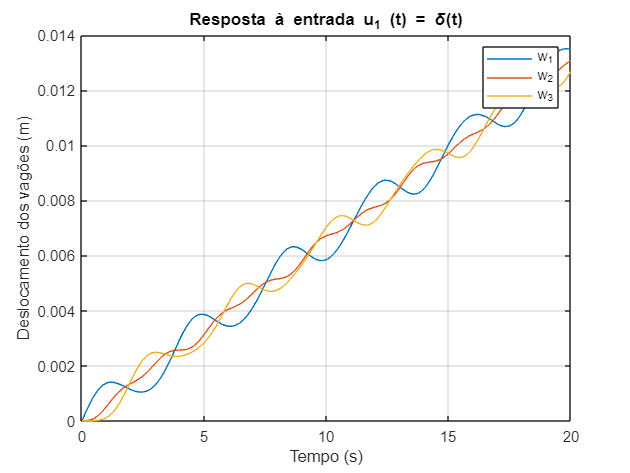

g = tf(sys);
G11 = g(1,1);
G21 = g(2,1);
G31 = g(3,1);
% função impulse para simular a resposta ao impulso
t = 0:0.01:20;  % vetor de tempo para a simulação
[w11, t] = impulse(G11, t);
[w21, t] = impulse(G21, t);
[w31, t] = impulse(G31, t);

% Resposta ao impulso
figure;
plot(t,w11)
hold on
plot(t,w21)
plot(t,w31)
grid on
legend('w_1','w_2','w_3')
title('Resposta à entrada u_1 (t) = \delta(t)')
xlabel('Tempo (s)')
ylabel('Deslocamento dos vagões (m)');
hold off;

### b) apenas para a entrada $u_2(t) = \delta(t)$; 

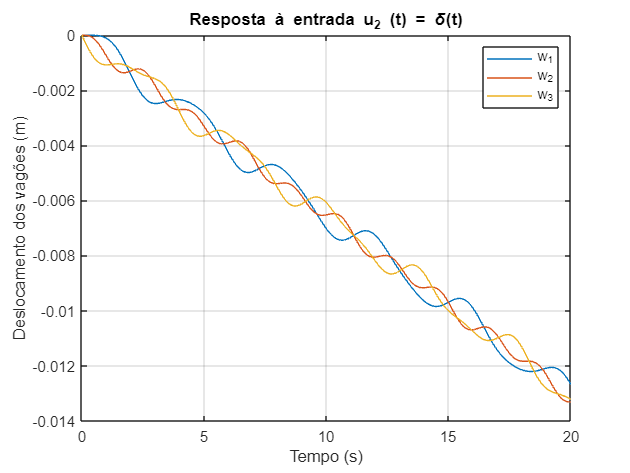

G12 = g(1,2);
G22 = g(2,2);
G32 = g(3,2);
% função impulse para simular a resposta ao impulso
t = 0:0.01:20;  % vetor de tempo para a simulação
[x12, t] = impulse(G12, t);
[x22, t] = impulse(G22, t);
[x32, t] = impulse(G32, t);

% Resposta ao impulso
figure;
plot(t,x12)
hold on
plot(t,x22)
plot(t,x32)
grid on
legend('w_1','w_2','w_3')
title('Resposta à entrada u_2 (t) = \delta(t)')
xlabel('Tempo (s)')
ylabel('Deslocamento dos vagões (m)');
hold off;

### c) para entradas $u_1(t) = u_2(t) = \delta(t)$. 

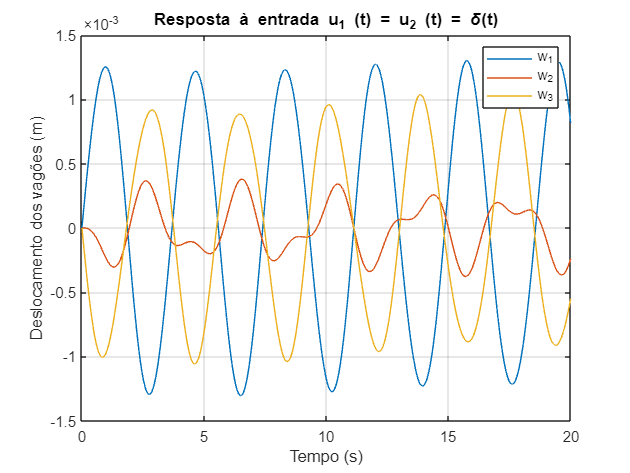

% Resposta ao impulso
x13 = x11 + x12;
x23 = x21 + x22;
x33 = x31 + x32;

figure;
plot(t,x13)
hold on
plot(t,x23)
plot(t,x33)
grid on
legend('w_1','w_2','w_3')
title('Resposta à entrada u_1 (t) = u_2 (t) = \delta(t)')
xlabel('Tempo (s)')
ylabel('Deslocamento dos vagões (m)');

### Apresente a resposta até 20 segundos. Unidades em SI.

### 2.3 Explique o comportamento visto para o caso $u_1(t) = u_2(t) = \delta(t)$.

Vemos através do último gráfico que as massas $m_1$ e $m_3$(onde $w_1$ e $w_3$ correspondem, respectivamente, a variação de seus deslocamentos em relação ao ponto ${\mathit{\mathbf{y}}}^*$), ficam oscilando de forma muito próxima a um movimento periódico em torno de seus pontos de equilíbrio ($L_1$,$L_2$ e $L_3$), e o vagão de massa $m_2$ se movimenta de acordo com a "necessidade" para que os vagões dos extremos mantenham seu movimento próximo ao periódico. Além disso, é visto que a massa $m_1$ se desloca uma distância maior do que $m_3$, isso ocorre porque a constante $k_1$ da mola associada à $m_1$ é menor do que a associada à $m_3$ ($k_2$).